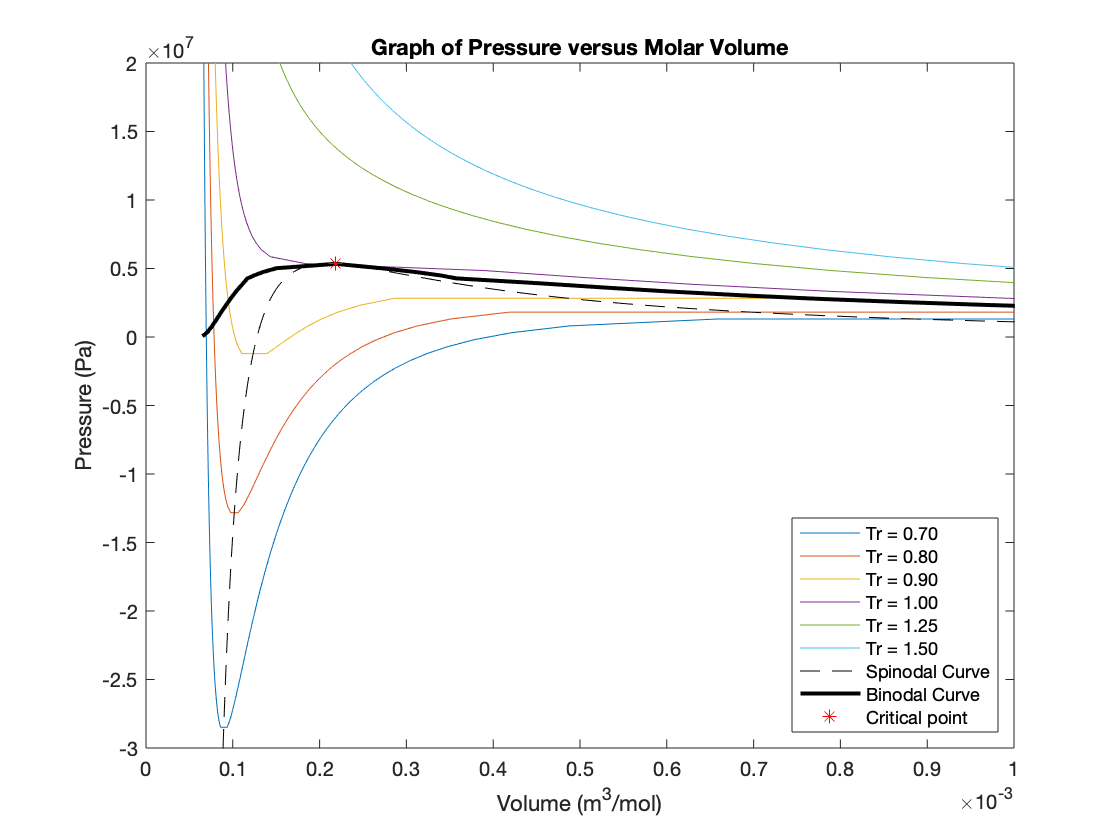

syms T V 

R = 8.314;
Ttriple = 180.97;
Tcrit = 437.22;
Pcrit = 5.34e+6;
antA = 4.29371;
antB = 995.445;
antC = -47.869;
Pant = @(T) (10^5)*10^(antA - (antB/(T + antC)));
b = 0.0778*R*Tcrit/Pcrit;

omega = -1 - log10(Pant(0.7*Tcrit)/Pcrit);
k_small = 0.37464 + 1.5422*omega - 0.26992*omega^2;
alpha_T = @(T) (1 + k_small*(1 - sqrt(T./Tcrit)))^2;
a_T = @(T) (0.45724*(R^2)*(Tcrit^2)/Pcrit) * alpha_T(T);

Prb = @(T,V) R*T./(V - b) - a_T(T)/(V.*(V + b) + b*(V - b));

dpdv = matlabFunction(diff(Prb,V));

Trange = Tcrit*[0.7,0.8,0.9,1,1.25,1.5];

Prange = linspace(-30e+6,20e+6,100);
    
for j = 1:length(Trange)    
    P_rangenew = [];  
    Varray = [];      
    for i = 1:length(Prange)  
        Vval = vpasolve(Prb(Trange(j),V) == Prange(i),V,[0 Inf])'; 
                                        
        n = numel(Vval);                               
    
        if n == 1                
            P_rangenew = [P_rangenew Prange(i)];  
            Varray = [Varray Vval(1)];           
        elseif n == 2
            P_rangenew = [P_rangenew Prange(i) Prange(i)]; 
            Varray = [Varray Vval(1) Vval(2)];             
        elseif n == 3                                       
            P_rangenew = [P_rangenew Prange(i) Prange(i) Prange(i)];
            Varray = [Varray Vval(1) Vval(2) Vval(3)];
        end
    end
    
    [Varray,sortIdx] = sort(Varray); 
    P_rangenew = P_rangenew(sortIdx); 
    plot(Varray,P_rangenew,'-')       
    hold on
end

P_spin = [];
V_spin = [];

Tnew = linspace(0,Tcrit,1000);

for k = 1:length(Tnew)
    Vval2 = vpasolve(dpdv(Tnew(k),V) == 0,V,[0 Inf])';
    m = numel(Vval2);
    if m == 2
        P_spin = [P_spin Prb(Tnew(k),Vval2(1)) Prb(Tnew(k),Vval2(2))];
        V_spin = [V_spin Vval2(1) Vval2(2)];
        
    elseif m == 1
        P_spin = [P_spin Prb(Tnew(k),Vval2(1))];
        V_spin = [V_spin Vval2(1)];
    elseif m == 3
        P_spin = [P_spin Prb(Tnew(k),Vval2(1)) Prb(Tnew(k),Vval2(2)) Prb(Tnew(k),Vval2(3))];
        V_spin = [V_spin Vval2(1) Vval2(2) Vval2(3)];
    end
end
[V_spin,sortIdx] = sort(V_spin); 
P_spin = P_spin(sortIdx); 
plot(V_spin,P_spin,'k--')

Trange = linspace(0,Tcrit,100);
Prange = linspace(Pcrit,-30e+6,1000); 

V_bin = [];
P_bin = [];
P_bin_nine = [];
T_bin_nine = [];

for j = 1:length(Trange)
    for i = 1:length(Prange)
        Vval3 = sort(vpasolve(Prb(Trange(j),V) == Prange(i),V,[0 Inf])');
        m = numel(Vval3);
        n = 1;
        if m == 3
            area = int(Prb(Trange(j),V) - Prange(i),V,Vval3(1),Vval3(3));
            if abs(area) <= 100
                V_bin = [V_bin Vval3(1) Vval3(3)];
                P_bin = [P_bin Prange(i) Prange(i)];
                P_bin_nine = [P_bin_nine Prange(i)];
                T_bin_nine = [T_bin_nine Trange(j)];
                n = n + 1;
                break
            end
        end  
        if n ~= 1
            break
            break
        end
    end
end

Vcrit = vpasolve(Prb(Tcrit,V) == Pcrit,V,[0 Inf]);
V_bin = [V_bin Vcrit];
P_bin = [P_bin Pcrit];

[V_bin,sortidx] = sort(V_bin);
P_bin = P_bin(sortidx);

plot(V_bin,P_bin,'k-','linewidth',2)
plot(Vcrit,Pcrit,'r*')

xlim([0 0.001])
ylim([-30e6 20e6])
xlabel('Volume (m^3/mol)')
ylabel('Pressure (Pa)')
title('Graph of Pressure versus Molar Volume')
legend({'Tr = 0.70','Tr = 0.80','Tr = 0.90','Tr = 1.00','Tr = 1.25','Tr = 1.50','Spinodal Curve','Binodal Curve','Critical point'},'Location','southeast')
hold off